# STS PHASE RECOGNITION BASED ON  GROUND REACTION FORCE

In the study of Etnyre et al [1] the Sit-To-Stand Movement (STS) is categorized in 11 recognizable events, based on the values of the Ground Reaction Force (GRF) registered through a Force Plate.

The present routine identifies 4 phases of the Sit-To-Stand starting relying on the definition gave by Etnyre.

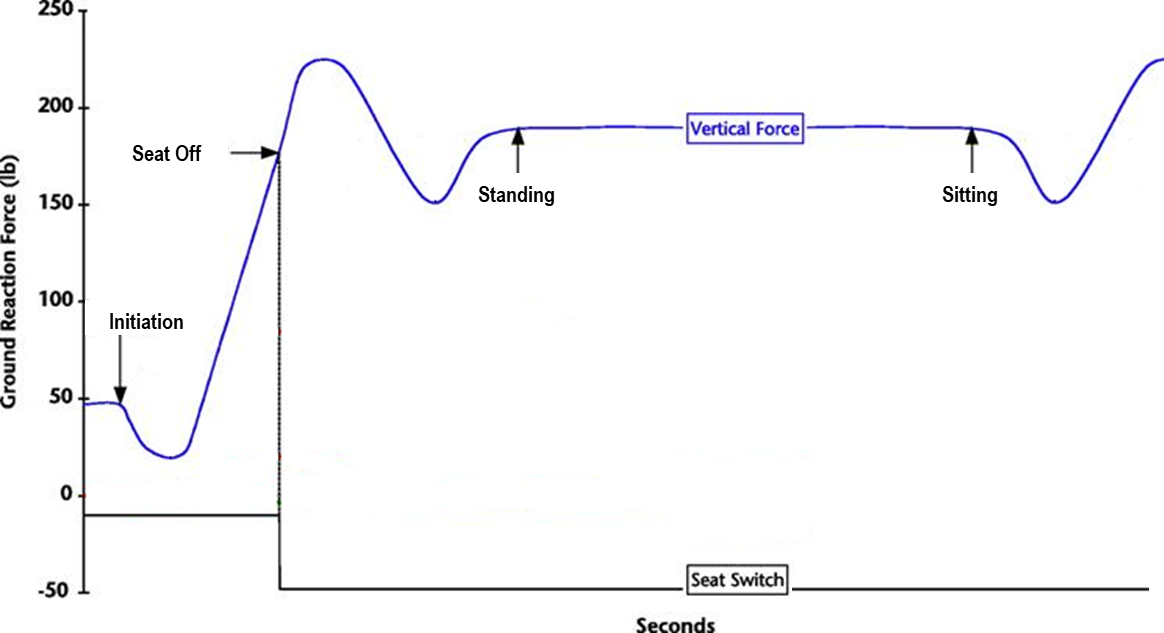

Modified by Etnyre B, Thomas DQ. (2007)

EVENTS

- Initiation: defined as the first deflection from baseline of the force platform recording (as defined by Etnyre)

- Seat-Off: registered through an electronic switch positioned on the chair to register the detachment of the thighs (as defined by Etnyre)

- Standing: determined as the first instant following the rebound recovery when the recording leveled to normal postural sway (as defined by Etnyre)

- Sitting: last instant of stable stance before the oscillations of the sitting movement

PHASES

- REST: from resting sitting position to Initiation;

- TRUNK LEANING: from Initiation to Seat Off;

- RAISING: from Seat Off to Standing;

- STANDING: from Standing to Sitting, identifying the stable stance;

You will be asked to visually identify the Initiation, the Standing, and the Sitting event in sequential order from various GRF profiles

% CLEAN MEMORY
clear
close all
clc

% 1-Define the folder containing the STS acquisition
KSFolder='Insert Folder path';

% 2-List of Subjects
SBJS=dir(fullfile(cd,KSFolder,'FMTS*'));

% 3-Test or Retest? 
retest=boolean(input('Test or Retest?\n0-test   1-retest\n'));
if retest
    % 4-In case of Retest take the results of the previous evaluation
    [file,path]=uigetfile()
    % 5-Load the same GRF sequences to evaluate reliability
    load([path,file],'countA','countB')
else  
    % 6-Define Indexes of 100 Sit-To-Stand movements at Self-Paced speed (countA)
    % and 100 at Controlled speed (countB)
    countA=[];
    countB=[];
    count=1;    
    % 7-Read the current f file (STS sequence) of the s Subject
    for s=1:numel(SBJS)
        FILES=dir(fullfile(cd,KSFolder,SBJS(s).name,'*STS*'));
        for f=1:numel(FILES)
            % 7a- If STSA, countA+1
            if FILES(f).name(27:30)=='STSA'
                countA=[countA,count];
            % 7b- If STSB, countB+1
            elseif FILES(f).name(27:30)=='STSB'
                countB=[countB,count];
            end
        count=count+1;
        end
    end
    % 8-Randomization
    RandA=randperm(numel(countA));
    RandB=randperm(numel(countB));
    countA=countA(RandA);countA=countA(1:100);
    countB=countB(RandB);countB=countB(1:100);
end
KSsamp=1024;    % Force plate sample frequency
count=1;
Initdiff=[];    % Difference between visual and automated assessments: Inititation 
Standdiff=[];   % Difference between visual and automated assessments: Standing
Sitdiff=[];     % Difference between visual and automated assessments: Sitting
Initv=[];       % Visual assessments: Inititation 
Standv=[];      % Visual assessments: Standing
Sitv=[];        % Visual assessments: Sitting

% (Control variables)
sbjcount=[];
trialcount=[];
typecount=[];

% 9-For each subject
for s=1:numel(SBJS)
    % 9a-Collect all the STS sequences
    FILES=dir(fullfile(cd,KSFolder,SBJS(s).name,'*STS*'));
    % 9b-For each file
    for f=1:numel(FILES)
        if or(ismember(count,countA),ismember(count,countB))
            % 9b1-Load the file
            load(fullfile(cd,KSFolder,SBJS(s).name,FILES(f).name));
            % 9b2-Extract data and pre-processing
            Data=class2struct(Data);
            [Fx,Fy,Fz,~,Bott,time]=ImportKS(Data);
            [Fx_cut,Fy_cut,Fz_cut,Bott_cut,KS_time_cut]=CutKS(Fx,Fy,Fz,Bott,time,KSsamp,1); % The first second of acquisition is trimmed out (sound of starting acquisition)
            [b,a]=butter(1,64/512);
            Fz_cut=filtfilt(b,a,Fz_cut);                        
            XStimecut=KS_time_cut(1):(1/50):KS_time_cut(end);   % The STS sequences were coregistered with inertial sensors this line of code simulate the time of the accelerometers
            KSresamp=interp1(KS_time_cut,Fz_cut,XStimecut);     % The force signal was resampled to match the frequency of inertial sensors
            Bott_cut=filtfilt(b,a,Bott_cut);
            % 9b3-Visual assessments:Initiation
            plot(KSresamp);
            [Initv(count),~]=ginput(1);
            Initv(count)=round(Initv(count));
            BottResamp=interp1(KS_time_cut,Bott_cut,XStimecut);
            ForceEp=Epochs_Force(KSresamp,0.1,50);
            % 9b4-Automated assessments: Initiation
            Inita=TrunkMOV(ForceEp,2);
            % 9b5-Visual assessments:Standing and Sitting
            [Balancev,~]=ginput(2);
            Standv(count)=round(Balancev(1));
            Sitv(count)=round(Balancev(2));
            try
                % 9b6-Automated assessments:SeatOff and SeatOn
                [SeatOff,SeatOn]=Bottom_Transition(BottResamp);
                % 9b7-Automated assessments:Standing and Sitting
                [Standa,Sita]=SteadyStandingPoints(KSresamp,50,0.1,SeatOff,SeatOn,1.5);
                Initdiff(count)=(Initv(count)-Inita);
                Standdiff(count)=(Standv(count)-Standa);
                Sitdiff(count)=(Sitv(count)-Sita);
                sbjcount(count)=s;
                trialcount(count)=f;
                typecount{count}=FILES(f).name(27:30);
            catch
                Initdiff(count)=NaN;
                Standdiff(count)=NaN;
                Sitdiff(count)=NaN;
                sbjcount(count)=s;
                trialcount(count)=f;
                typecount{count}=FILES(f).name(27:30);
            end
        else
            Initdiff(count)=NaN;
            Standdiff(count)=NaN;
            Sitdiff(count)=NaN;
            Initv(count)=NaN;
            Sitv(count)=NaN;
            Standv(count)=NaN;
            sbjcount(count)=s;
            trialcount(count)=f;
            typecount{count}=FILES(f).name(27:30);
        end
        count=count+1;        
    end
end 
save("NameSurname_T_Date_Hour.mat",'countA','countB','Initdiff','Standdiff','Sitdiff','sbjcount','trialcount','typecount','Initv','Standv','Sitv')


# References

[1] Etnyre B, Thomas DQ. Event standardization of sit-to-stand movements. *Phys Ther*. 2007;87(12):1651‐1666. doi:10.2522/ptj.20060378